# Workflow HDF5 peakData Analysis Plot

This workflow shows different possibilities to plot data with the variable peakLaser.mat or peakVoltage.mat from the Workflow_Calculate_H.mlx and Workflow_HDF5_measurement_condition.mlx

Both are table variables containing the specimen temperature, AnalysisUHV, pulsePeriod and pulseFraction/pulseEnergy for Voltage/Laser measurements

Following plots are contained in this workflow

- Load data 

- H conc vs AnalysisUHV

- H conc vs specimen Temperature

- H conc vs pulsePeriod

- Laser Measurement plots

- Voltage Measurement plots

- Save Image

## 1. Load the data

load('L:\existingHDF5files\peakLaser.mat')
load('L:\existingHDF5files\peakVoltage.mat')

## 2. H conc vs AnalysisUHV

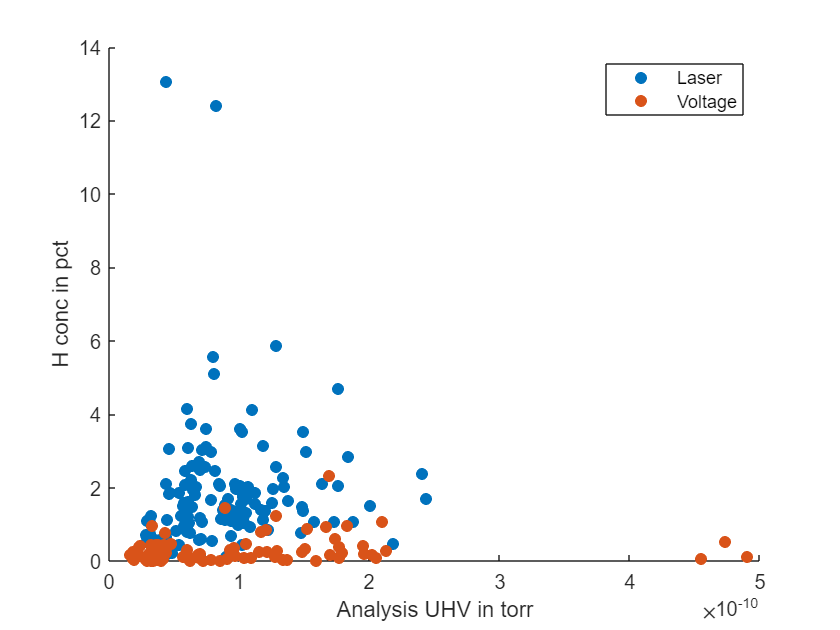

figure;
scatter(peakLaser.AnalysisUHV, peakLaser.pctNew, 'filled', 'MarkerFaceColor',  blau(1,:), 'DisplayName', 'Laser');
hold on
scatter(peakVoltage.AnalysisUHV, peakVoltage.pctNew, 'filled', 'MarkerFaceColor',  gelb(1,:), 'DisplayName', 'Voltage');
legend
ylabel('H conc in pct');
xlabel('Analysis UHV in torr');

### H conc vs AnalysisUHV with pulsePeriod

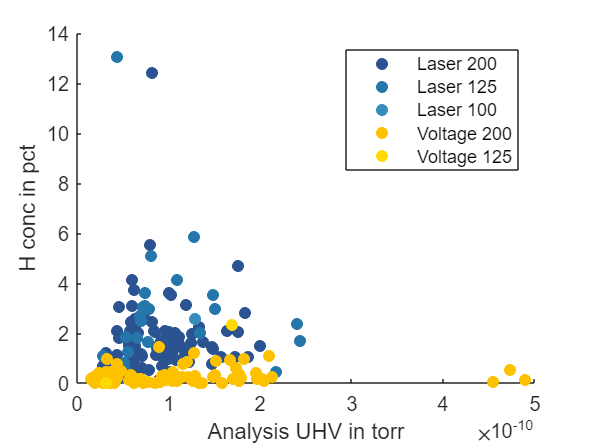

figure;
attrLaser = flip(unique(peakLaser.pulsePeriod));
for i = 1:length(attrLaser)
    scatter(peakLaser.AnalysisUHV(peakLaser.pulsePeriod == attrLaser(i)), peakLaser.pctNew(peakLaser.pulsePeriod == attrLaser(i)), 'filled', 'MarkerFaceColor',  blau(i,:), 'DisplayName', ['Laser ' num2str(attrLaser(i))]);
    hold on
end
attrVoltage = flip(unique(peakVoltage.pulsePeriod));
for i = 1:length(attrVoltage)
    scatter(peakVoltage.AnalysisUHV(peakVoltage.pulsePeriod == attrVoltage(i)), peakVoltage.pctNew(peakVoltage.pulsePeriod == attrVoltage(i)), 'filled', 'MarkerFaceColor',  gelb(i,:),'DisplayName', ['Voltage ' num2str(attrVoltage(i))]);
    hold on
end

legend
ylabel('H conc in pct');
xlabel('Analysis UHV in torr');

## 3. H conc vs specimen Temperature

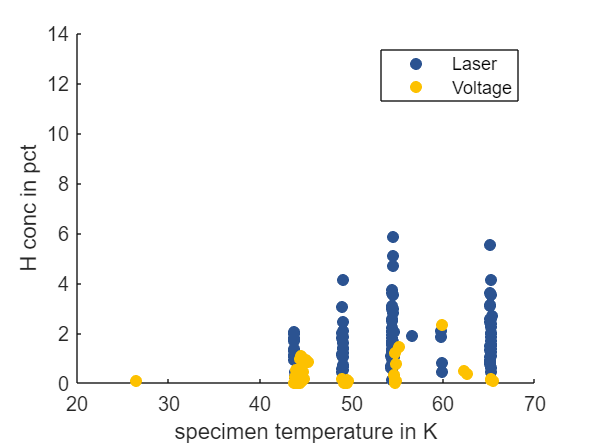

figure;
scatter(peakLaser.SpecTemp, peakLaser.pctNew, 'filled', 'DisplayName', 'Laser', 'MarkerFaceColor',blau(1,:));
hold on
scatter(peakVoltage.SpecTemp, peakVoltage.pctNew, 'filled', 'DisplayName', 'Voltage', 'MarkerFaceColor',gelb(1,:));
legend
ylabel('H conc in pct');
xlabel('specimen temperature in K');

## 4. H conc vs pulsePeriod

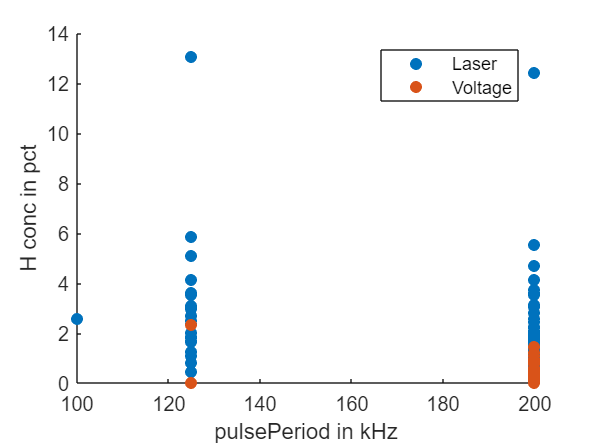

figure;
scatter(peakLaser.pulsePeriod, peakLaser.pctNew, 'filled', 'DisplayName', 'Laser');
hold on
scatter(peakVoltage.pulsePeriod, peakVoltage.pctNew, 'filled', 'DisplayName', 'Voltage');
legend
ylabel('H conc in pct');
xlabel('pulsePeriod in kHz');

## 5. Laser measurement plots

### H conc vs pulse Energy

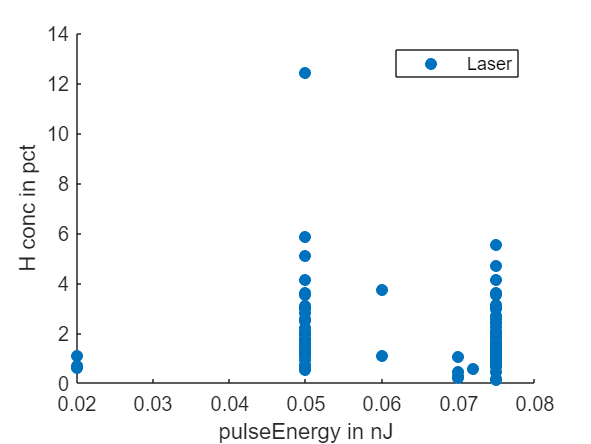

figure;
scatter(peakLaser.pulseEnergy, peakLaser.pctNew, 'filled', 'DisplayName', 'Laser');
legend
ylabel('H conc in pct');
xlabel('pulseEnergy in nJ');

### H conc vs Analysis UHV in dependence of pulsePeriod

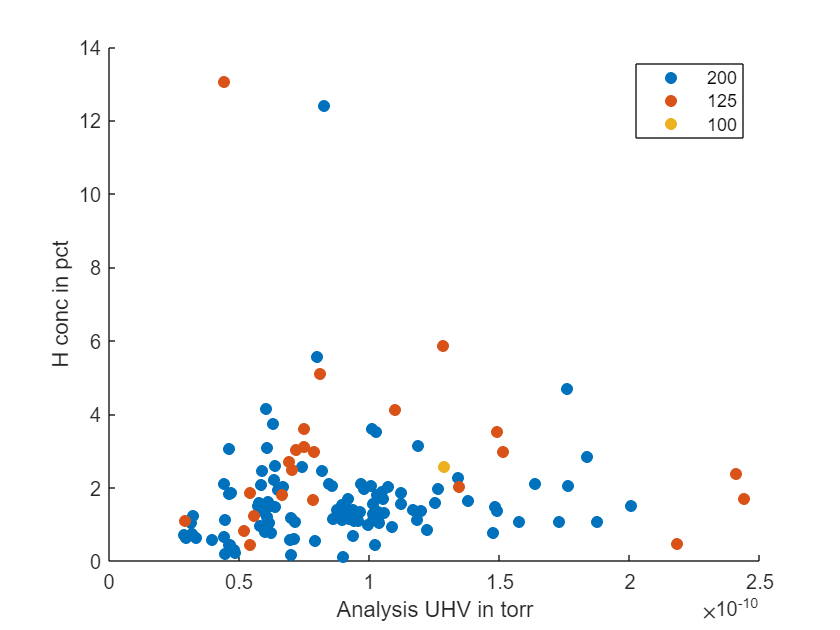

attr = flip(unique(peakLaser.pulsePeriod));
figure;
for i = 1:length(attr)
    scatter(peakLaser.AnalysisUHV(peakLaser.pulsePeriod == attr(i)), peakLaser.pctNew(peakLaser.pulsePeriod == attr(i)), 'filled', 'DisplayName', num2str(attr(i)));
    hold on
end
legend
ylabel('H conc in pct');
xlabel('Analysis UHV in torr');

### H conc vs Analysis UHV in dependence of pulseEnergy

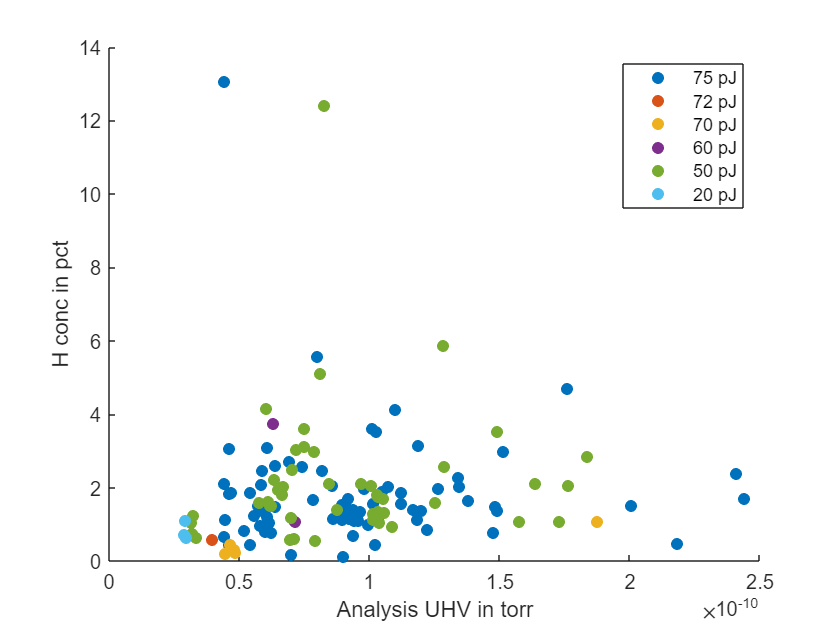

attr = flip(unique(peakLaser.pulseEnergy));
figure;
for i = 1:length(attr)
    scatter(peakLaser.AnalysisUHV(peakLaser.pulseEnergy == attr(i)), peakLaser.pctNew(peakLaser.pulseEnergy == attr(i)), 'filled', 'DisplayName', [num2str(attr(i)*1000) ' pJ']);
    hold on
end
legend
ylabel('H conc in pct');
xlabel('Analysis UHV in torr');

### H conc vs Analysis UHV in dependence of specimen Temperature

Specimen temperature is rounded to have a clearer overview

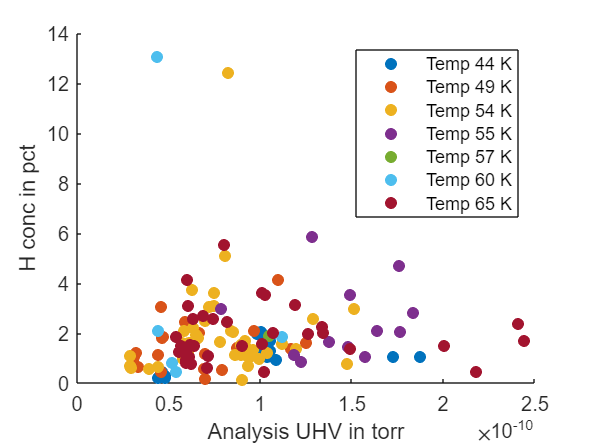

specNewTemp = round(peakLaser.SpecTemp);
attr = unique(specNewTemp);
figure;
for i = 1:length(attr)
   scatter(peakLaser.AnalysisUHV(specNewTemp == attr(i)), peakLaser.pctNew(specNewTemp == attr(i)), 'filled', 'DisplayName', ['Temp ' num2str(attr(i)) ' K']);
   hold on
end
legend
ylabel('H conc in pct');
xlabel('Analysis UHV in torr');

### H conc vs specimen Temperature

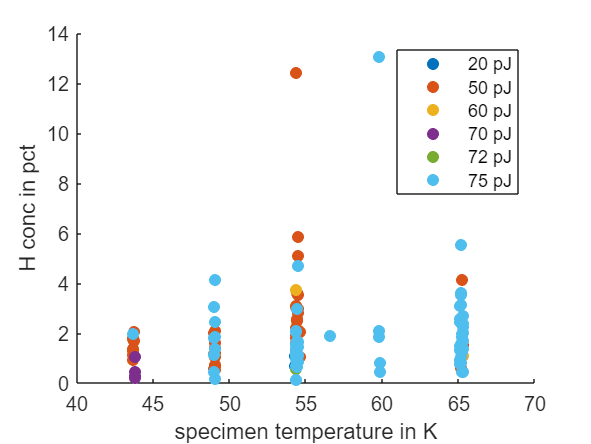

attr = unique(peakLaser.pulseEnergy);
figure;
for i = 1:length(attr)
    scatter(peakLaser.SpecTemp(peakLaser.pulseEnergy == attr(i)), peakLaser.pctNew(peakLaser.pulseEnergy == attr(i)), 'filled', 'DisplayName', [num2str(attr(i)*1000) ' pJ']);
    hold on
end
legend
ylabel('H conc in pct');
xlabel('specimen temperature in K');

## 6. Voltage measurement plots

### H conc vs Analysis UHV in dependence of pulsePeriod

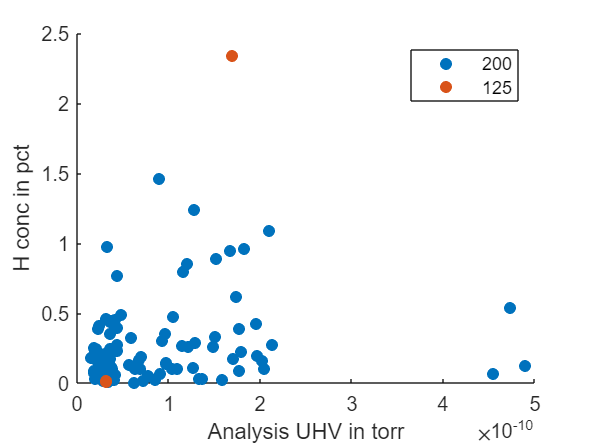

figure;
attr = flip(unique(peakVoltage.pulsePeriod));
for i = 1:length(attr)
    scatter(peakVoltage.AnalysisUHV(peakVoltage.pulsePeriod == attr(i)), peakVoltage.pctNew(peakVoltage.pulsePeriod == attr(i)), 'filled', 'DisplayName', [num2str(attr(i))]);
    hold on
end

legend
ylabel('H conc in pct');
xlabel('Analysis UHV in torr');

### H conc vs Analysis UHV in dependence of pulseFraction

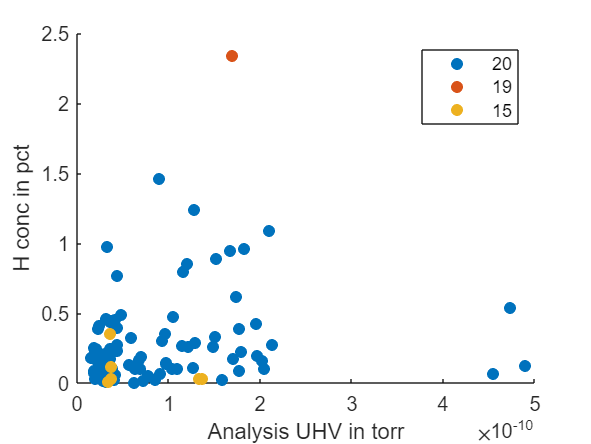

attr = flip(unique(peakVoltage.pulseFraction));
figure;
for i = 1:length(attr)
    scatter(peakVoltage.AnalysisUHV(peakVoltage.pulseFraction == attr(i)), peakVoltage.pctNew(peakVoltage.pulseFraction == attr(i)), 'filled', 'DisplayName', num2str(attr(i)));
    hold on
end
legend
ylabel('H conc in pct');
xlabel('Analysis UHV in torr');

### H conc vs Analysis UHV in dependence of specimen Temperature

Specimen temperature is rounded to have a clearer overview

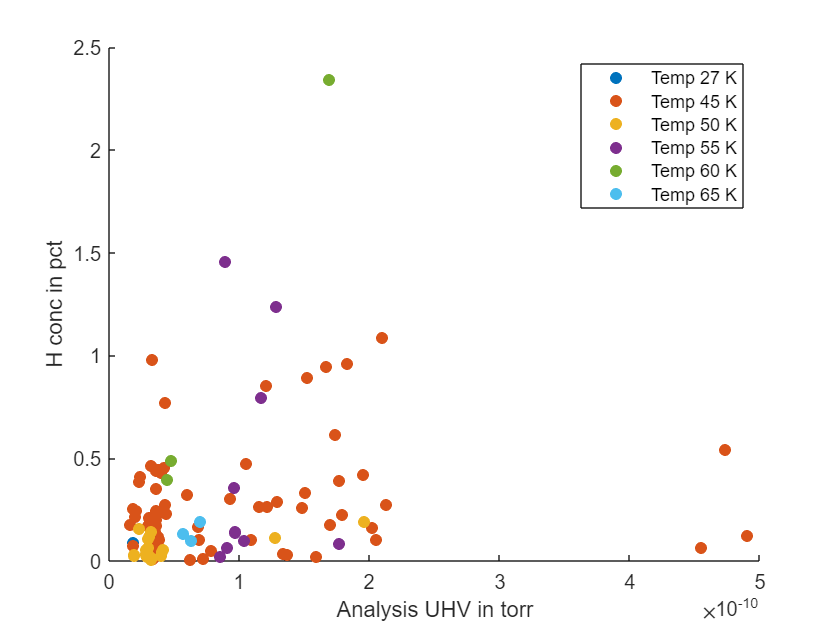

specNewTemp = round(peakVoltage.SpecTemp);

specNewTemp(specNewTemp == 44) = 45;
specNewTemp(specNewTemp == 49) = 50;
specNewTemp(specNewTemp == 62) = 60;
specNewTemp(specNewTemp == 63) = 60;
attr = unique(specNewTemp);
figure;
for i = 1:length(attr)
   scatter(peakVoltage.AnalysisUHV(specNewTemp == attr(i)), peakVoltage.pctNew(specNewTemp == attr(i)), 'filled', 'DisplayName', ['Temp ' num2str(attr(i)) ' K']);
   hold on
end
legend
ylabel('H conc in pct');
xlabel('Analysis UHV in torr');

### 7. Save figure

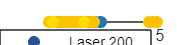

fig = gcf;
       
        nameForSave = "";
        savefig(fig, nameForSave);
        saveas(fig,nameForSave,'tif');
        exportgraphics(fig,[string(nameForSave) + ".eps"],'Resolution',600);